# **Simulações de antenas *****microstrip***** com células SRR**

`por Renan Machado`

Este é um *live script* em MatLAB que visa construir um *dataset* de simulações de antenas para treinar modelos preditivos de *machine learning*. Os parâmetros das antenas, como largura e comprimento do *patch*, disposição das células SRR, e outros, serão variados em uma faixa de valores adequados, procurando respeitar as referências oferecidas pela literatura. O *software* utilizado para as simulações eletromagnéticas é o **CST Studio Lite©**, utilizando o módulo **Microwave Studio**. Para o controle automatizado do software, será utilizada a API desenvolvida por Symeon Symeonidis, Stefanos Tsantilas e Stelios Mitilineos, tendo o código fonte e a documentação disponíveis [aqui](https://github.com/simos421/CST-MATLAB-API).

## Inicialização do CST

Para correta utilização da API, antes é necessário adicionar seu código fonte ao *path*, dessa forma:

addpath(genpath('CST-MATLAB-API-master'));

Para iniciar a aplicação do CST, utilizamos o seguinte comando:

cst = actxserver('CSTStudio.application');

Agora, com o CST aberto, podemos inicializar o Microwave Studio.

mws = cst.invoke('NewMWS');

Você deve ter na sua tela algo parecido como a figura abaixo.

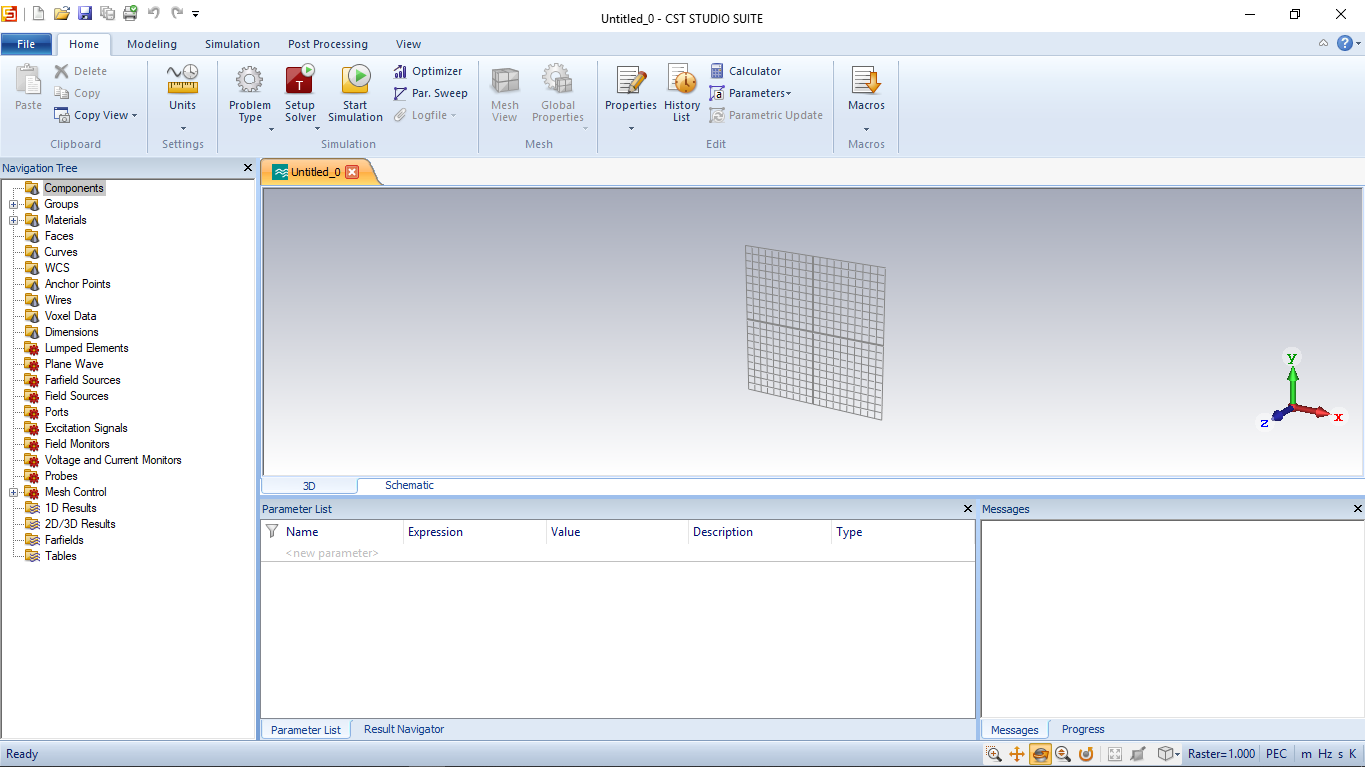

## Configurando o ambiente de simulação

Inicialmente, precisamos definir as unidades padrão. Com isso, também é necessário definir o intervalo de frequência que será simulado. Assim, é possível inicializar a *mesh* e definir as condições de contorno.

Aqui, a frequência será todo o domínio das bandas L, S, C, X, Ku e K, tendo o valor mínimo de 1GHz até 26,5 GHz.

fcenter = 3.5;
fmin = fcenter * 0.97

fmin = 3.3950

fmax = fcenter * 1.03

fmax = 3.6050

Em código:

CstDefineUnits(mws, 'um', 'GHz', 's', 'Kelvin', 'V', 'A', 'Ohm', 'S', 'PikoF', 'NanoH');
CstDefineFrequencyRange(mws, fmin, fmax);
CstMeshInitiator(mws); 

A antena estará no espaço livre, então:

%Condições de contorno
Xmin = 'expanded open';
Xmax = 'expanded open';
Ymin = 'expanded open';
Ymax = 'expanded open';
Zmin = 'expanded open';
Zmax = 'expanded open';

CstDefineOpenBoundary(mws, fmin, Xmin, Xmax, Ymin, Ymax, Zmin, Zmax);

Em seguida, precisamos definir o material do fundo:

XminSpace = 0;
XmaxSpace = 0;
YminSpace = 0;
YmaxSpace = 0;
ZminSpace = 0;
ZmaxSpace = 0;

CstDefineBackroundMaterial(mws, XminSpace, XmaxSpace, YminSpace, YmaxSpace, ZminSpace, ZmaxSpace);

## Definição de materiais

Para a definição de materiais que serão utilizados nos componentes, é preciso definir as propriedades do material de acordo com a biblioteca do CST e fazer uma função em MatLAB com todas essas propriedades, juntamente com o nome do material. Somente depois disso é que podemos utilizar o nome do material no código. Na API, já temos funções para definir materiais como cobre e FR4 com perdas.

metal = CstCopperAnnealedLossy(mws)

metal = 'Copper (annealed)'

[dieletric, epsilon_r] = CstFR4lossy(mws)

dieletric = 'FR-4 (lossy)'

epsilon_r = 4.3000

Além disso, precisamos definir a altura da folha de metal (nesse caso, cobre).

t = 0.035*1e3; % in um (t from thickness)

## Determinando W

Para uma obtermos uma boa eficiência de radiação, (BALANIS, 2005) nos dá que:


$$W=\frac{c}{2f_r }\sqrt{\;\frac{2}{{\epsilon \;}_r +1}}$$


W = 3e8/(2*fcenter*1e9)*sqrt(2/(epsilon_r+1))*1e6 % in um

W = 2.6327e+04

## Intervalo de valores para a antena

As variáveis associadas a geometria de uma antena *microstrip* são essas mostradas na figura abaixo. Alguns intervalos estão em função do comprimento de onda $\lambda$, de forma que:


$$\lambda =\frac{c}{f}$$


f_step = 100e-3;
f = fmin:f_step:fmax % in GHz (1e9 Hz)

f =     3.3950    3.4950    3.5950


lambda = 3e5./f % in um (1e-6 m)

lambda = 	1.0e+04 *

    8.8365    8.5837    8.3449


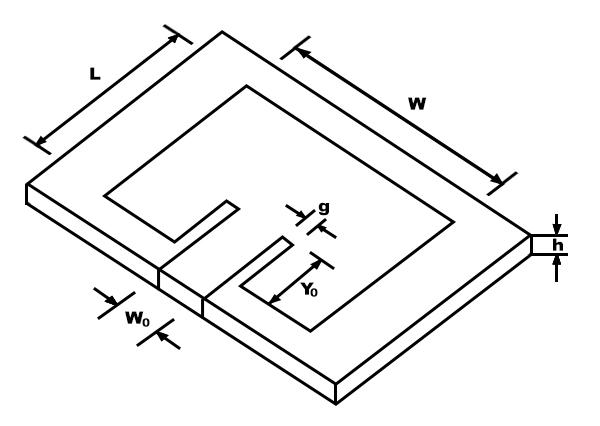

De acordo com a literatura, temos que:


$$0,003\lambda \;\le h\le 0,05\lambda$$


hmin = 0.003;
hmax = 0.05;
h_step = (hmax - hmin)/(4 - 1);

[h_factor, h] = GetAntennaValues(hmin, hmax, h_step, lambda)

h_factor =     0.0030    0.0187    0.0343    0.0500


h = 	1.0e+03 *

    0.2651    0.2575    0.2503
    1.6495    1.6023    1.5577
    3.0339    2.9471    2.8651
    4.4183    4.2918    4.1725


Antes de definirmos $L$, precisamos calcular a constante dielétrica efetiva da antena, já que algumas ondas viajam no substrato e algumas no ar. Segundo (BALANIS, 2005):


$$\epsilon_{\mathrm{reff}} =\frac{\epsilon_r +1}{2}+\frac{\epsilon_r -1}{2}{\left(1+12\;\frac{h}{W}\right)}^{-\frac{1}{2}}$$


epsilon_reff = (epsilon_r+1)/2+((epsilon_r-1)/2).*(1+(12/W).*h).^(-1/2)

epsilon_reff =     4.2085    4.2109    4.2132
    3.8966    3.9044    3.9118
    3.7189    3.7279    3.7366
    3.6004    3.6097    3.6186


Agora que temos a constante dielétrica efetiva, calculamos o quão maior o patch aparenta ser do que realmente é através de:


$$\Delta L=0,412h\;\frac{\left(\epsilon_{\mathrm{reff}} +0,3\right)\left(\frac{W}{h}+0,264\right)}{\left(\epsilon_{\mathrm{reff}} -0,258\right)\left(\frac{W}{h}+0,8\right)}$$


delta_l = 0.412.*h.*((epsilon_reff+0.3).*(W./h+0.264))./((epsilon_reff-0.258).*(W./h+0.8))

delta_l = 	1.0e+03 *

    0.1240    0.1204    0.1171
    0.7587    0.7375    0.7174
    1.3694    1.3318    1.2963
    1.9558    1.9032    1.8534


Finalmente, temos que:


$$L=\frac{c}{2f_r \sqrt{\epsilon_{\mathrm{reff}} }}-2\Delta L$$


l = 3e5./(2*fcenter*sqrt(epsilon_reff))-2.*delta_l

l = 	1.0e+04 *

    2.0643    2.0644    2.0645
    2.0193    2.0214    2.0234
    1.9485    1.9533    1.9579
    1.8675    1.8751    1.8823


Por último, os parâmetros restantes normalmente estão nessa faixa de valores:


$$0,1L\le Y_0 \le \frac{L}{3}$$



$$\frac{W}{6}\le W_0 \le 0,25W$$



$$0,2W_0 \le g\le 0,5W_0$$


y0min = 0.1;
y0max = 1/3;
[l_rows, l_cols] = size(l);
y0_step = (y0max - y0min)/(l_rows-1);

[y0_factor, y0] = GetAntennaValues(y0min, y0max, y0_step, l)

y0_factor =     0.1000    0.1778    0.2556    0.3333


y0 = 	1.0e+03 *

    2.0643    2.0644    2.0645
    3.5900    3.5937    3.5972
    4.9795    4.9918    5.0034
    6.2249    6.2504    6.2743


w0min = 1/6;
w0max = 0.25;
w0_step = (w0max - w0min)/(3 - 1);

[w0_factor, w0] = GetAntennaValues(w0min, w0max, w0_step, W)

w0_factor =     0.1667    0.2083    0.2500


w0 = 	1.0e+03 *

    4.3878
    5.4848
    6.5817


gmin = 0.2;
gmax = 0.5;
g_step = (gmax - gmin)/(length(w0_factor)-1);

[g_factor, g] = GetAntennaValues(gmin, gmax, g_step, w0)

g_factor =     0.2000    0.3500    0.5000


g = 	1.0e+03 *

    0.8776
    1.9197
    3.2909


Vamos transformar todos os parâmetros que estão em forma de matriz em um array linear através da função *Flat. *Essa função também remove os valores duplicados e ordena do menor para o maior.

H = Flat(h);
L = Flat(l);
Y0 = Flat(y0(:,1));
W0 = Flat(w0);
G = Flat(g);

## Intervalo de valores para as células SRR

% TODO

## Simulação

for h = 1:length(H)
    for l = 1:length(L)
        for y0 = 1:length(Y0)
            for w0 = 1:length(W0)
                for g = 1:length(G)
                    DrawMicrostripAntenna(mws, W, L(l), t, H(h), Y0(y0), W0(w0), G(g), metal, dieletric);
                    DrawPort(mws, W, L(l), t, H(h), W0(w0));
                end
            end
        end
    end
end